# Creating Generalized Stochastic Petri Nets (or GSPNRs):

This toolbox provides implementation of Generalized Stochastic Petri Nets using the custom [class](matlab:open('../src/models/@GSPNR/GSPNR.m')) GSPNR.

There are various ways to instantiate a GSPNR model:

- Using the GSPNR class methods to incrementally add elements to your model;

- Using an external graphical tool, either [GreatSPN](http://www.di.unito.it/~amparore/mc4cslta/editor.html) or [PIPE](http://pipe2.sourceforge.net/), to create your GSPNR and then import it to MATLAB;

- Using a mixed approach;

## Creating and Editing GSPNR Models with its class methods

As an example, we will create the GSPNR found below:

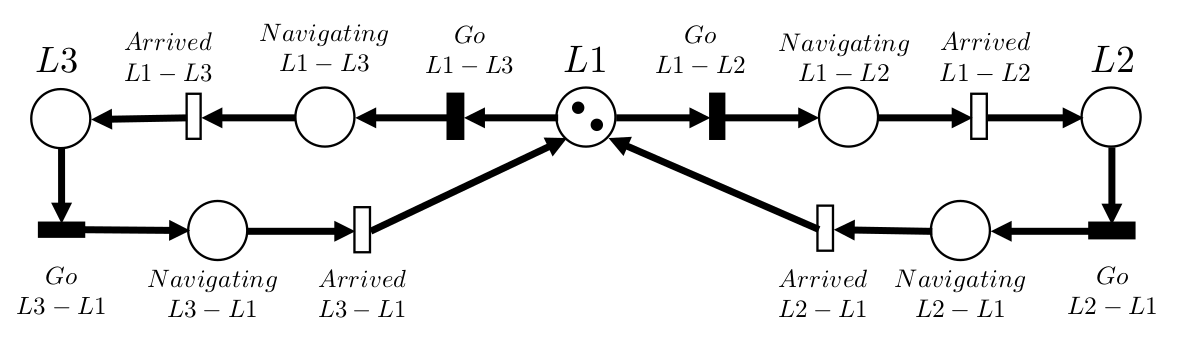

To create a GSPNR Model first instantiate an empty object:

Model = GSPNR();

To this empty model, you can add any number of elements that are used in GSPNRs: 

### Adding Places

Use the add_places method:

places = ["L1", "L2", "L3", "NavigatingL1-L3", ...
          "NavigatingL3-L1", "NavigatingL1-L2", ...
          "NavigatingL2-L1"];
tokens = [2, 0, 0, 0, 0, 0, 0];
Model.add_places(places, tokens);

This function takes a two input variables: the first one is an array of strings that are the place names, and the second one an array of non-negative integer specifying the initial number of tokens in each place. These two arrays must have be row vectors of the same same length.

### Adding Transitions

Use the add_transitions method:

transitions = ["GoL1-L3", "GoL3-L1", "GoL1-L2", "GoL2-L1", ...
               "ArrivedL1-L3", "ArrivedL3-L1", "ArrivedL1-L2", "ArrivedL2-L1"];
types       = ["imm", "imm", "imm", "imm", "exp", "exp", "exp", "exp"];
rates       = [0, 0, 0, 0, 2, 5, 0.5, 8];
Model.add_transitions(transitions,types,rates);

This method takes as input three row vectors of the same length: the first input is an array of strings that specify the transition names, the second input is an array of strings specifying if each transition is either immediate or exponential, and finally the third input is an array of positive floats, specifying either the rate (for exponential transitions) or weight (for immediate transitions).

### Adding Arcs

Use the add_arcs method:

arc_places =        ["L1","NavigatingL1-L3","NavigatingL1-L3","ArrivedL1-L3","L3",...
                     "NavigatingL3-L1","NavigatingL3-L1","L1","L1","NavigatingL1-L2",...
                     "NavigatingL1-L2","ArrivedL1-L2","L2","NavigatingL2-L1",...
                     "NavigatingL2-L1","L1"];    
arc_transitions =   ["GoL1-L3","GoL1-L3","ArrivedL1-L3","L3","GoL3-L1","GoL3-L1","ArrivedL3-L1",...
                     "ArrivedL3-L1","GoL1-L2","GoL1-L2","ArrivedL1-L2","L2","GoL2-L1","GoL2-L1",...
                     "ArrivedL2-L1",   "ArrivedL2-L1"];
arc_type =          ["in","out","in","out","in","out","in","out","in","out", "in","out","in","out",...
                    "in","out"];
arc_weights =       [1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1];
Model.add_arcs(arc_places, arc_transitions, arc_type, arc_weights);

This method takes as input four row vectors of the same length, where each element of each array specifies some characteristic for each arc. 

The first input is an array of strings specifying to which places the arcs are connected to, the second one is also an array of strings specifying the transitions to which the arcs are connected to, the third one specifies if the arc is an input or output arc (each element of this array should be either "in" for input arcs and "out" for output arcs). Finally, the fourth array is an array of non-negative integers, specifying the weight of each arc.

### Adding Rewards

Use the set_reward_functions():

reward_names = ["NavigatingL1-L3", "GoL1-L3"];
reward_values = [1, 5];
reward_types = ["place", "transition"];
Model.set_reward_functions(reward_names, reward_values, reward_types)

This method takes as input three row vectors of the same length, where each element of the first array specifies where the reward should be placed, each element of the second array specifies what the corresponding reward is, and the third array specifies for each reward if its a transition or place reward.

## Importing from [GreatSPN](http://www.di.unito.it/~amparore/mc4cslta/editor.html) or [PIPE](http://pipe2.sourceforge.net/)

The toolbox also supports compatibility with two open source projects that provide a GUI to create GSPNRs. These are the GreatSPN project, and the Platform Independent Petri net Editor (PIPE) project.

### To import from the GreatSPN format:

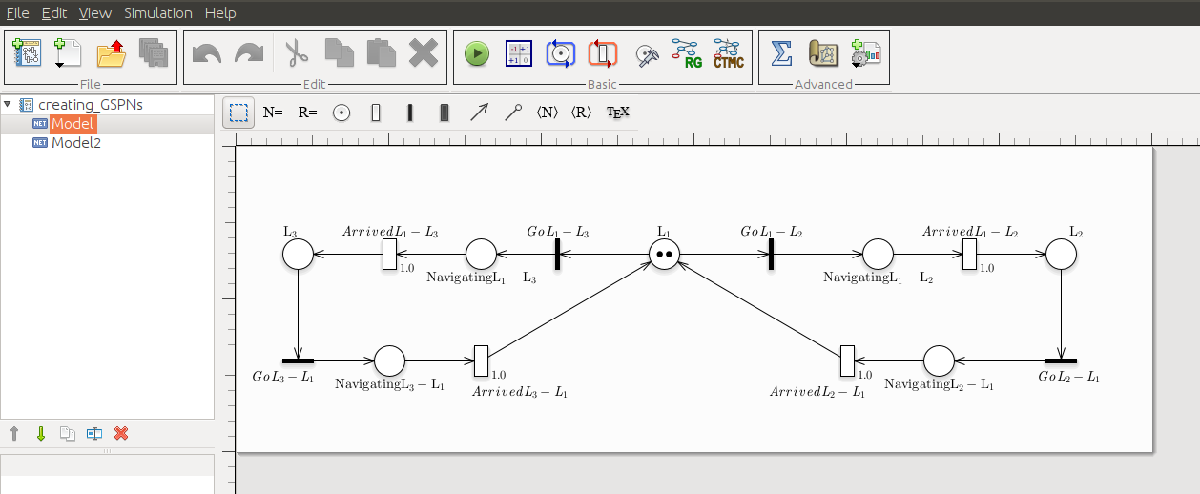

PNPRO_path = 'creating_GSPNs.PNPRO';
[nGSPN, gspn_list] = ImportfromGreatSPN(PNPRO_path);

The ImportfromGreatSPN utility function reads the project file (with ".PNPRO" extension) and automatically instantiates the GSPNR class for each GSPN found in the project file. Its first output is an integer that saves the number of GSPNs imported, and the second output is a structure with the GSPNR objects imported. The GSPNRs can be accessed by their fieldname, which is the same as the one used in the GreatSPN.

first_GSPNR  = gspn_list.Model

first_GSPNR =   GSPNR with properties:

                places: ["L1"    "L3"    "L2"    "NavigatingL3-L1"    "NavigatingL2-L1"    "NavigatingL1-L3"    "NavigatingL1-L2"]
           transitions: ["GoL1-L3"    "GoL1-L2"    "GoL3-L1"    "GoL2-L1"    "ArrivedL1-L3"    "ArrivedL3-L1"    "ArrivedL1-L2"    "ArrivedL2-L1"]
      type_transitions: ["imm"    "imm"    "imm"    "imm"    "exp"    "exp"    "exp"    "exp"]
      rate_transitions: [0 0 0 0 1 1 1 1]
            input_arcs: [7×8 double]
           output_arcs: [8×7 double]
                  arcs: [1×1 struct]
       initial_marking: [2 0 0 0 0 0 0]
       current_marking: [2 0 0 0 0 0 0]
         place_rewards: [0 0 0 0 0 0 0]
    transition_rewards: [0 0 0 0 0 0 0 0]


second_GSPNR = gspn_list.Model2

second_GSPNR =   GSPNR with properties:

                places: ["L1"    "L3"    "L2"    "NavigatingL3-L1"    "NavigatingL2-L1"    "NavigatingL1-L3"    "NavigatingL1-L2"]
           transitions: ["GoL1-L3"    "GoL1-L2"    "GoL3-L1"    "GoL2-L1"    "ArrivedL1-L3"    "ArrivedL3-L1"    "ArrivedL1-L2"    "ArrivedL2-L1"]
      type_transitions: ["imm"    "imm"    "imm"    "imm"    "exp"    "exp"    "exp"    "exp"]
      rate_transitions: [0 0 0 0 1 1 1 1]
            input_arcs: [7×8 double]
           output_arcs: [8×7 double]
                  arcs: [1×1 struct]
       initial_marking: [2 0 0 0 0 0 0]
       current_marking: [2 0 0 0 0 0 0]
         place_rewards: [0 0 0 0 0 0 0]
    transition_rewards: [0 0 0 0 0 0 0 0]


#### Important! To correctly import from GreatSPN, the GSPNs must be created in the correct format inside GreatSPN:

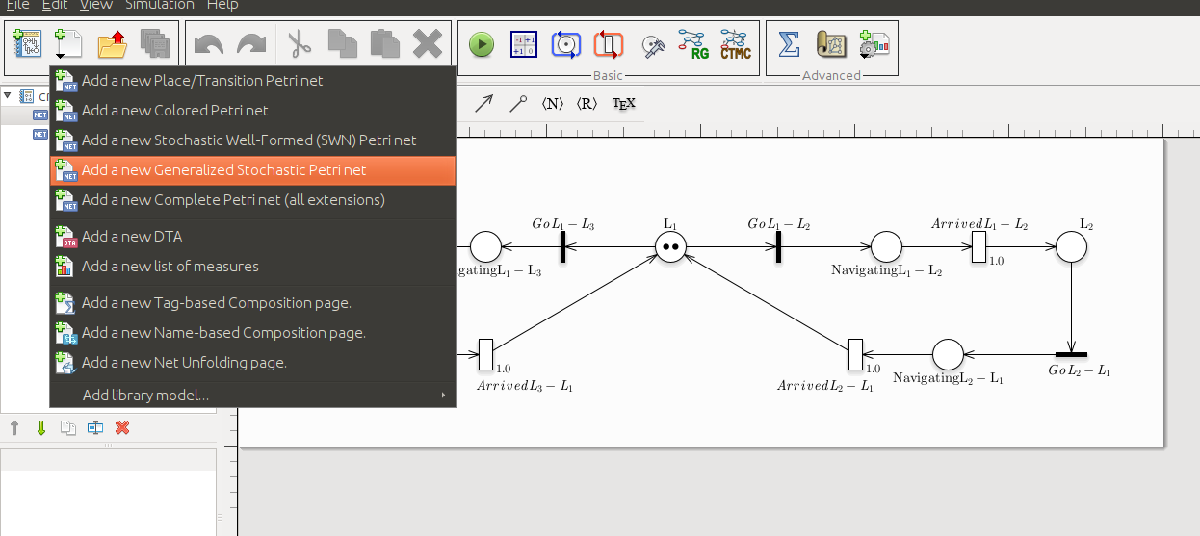

### To import from the PIPE format:

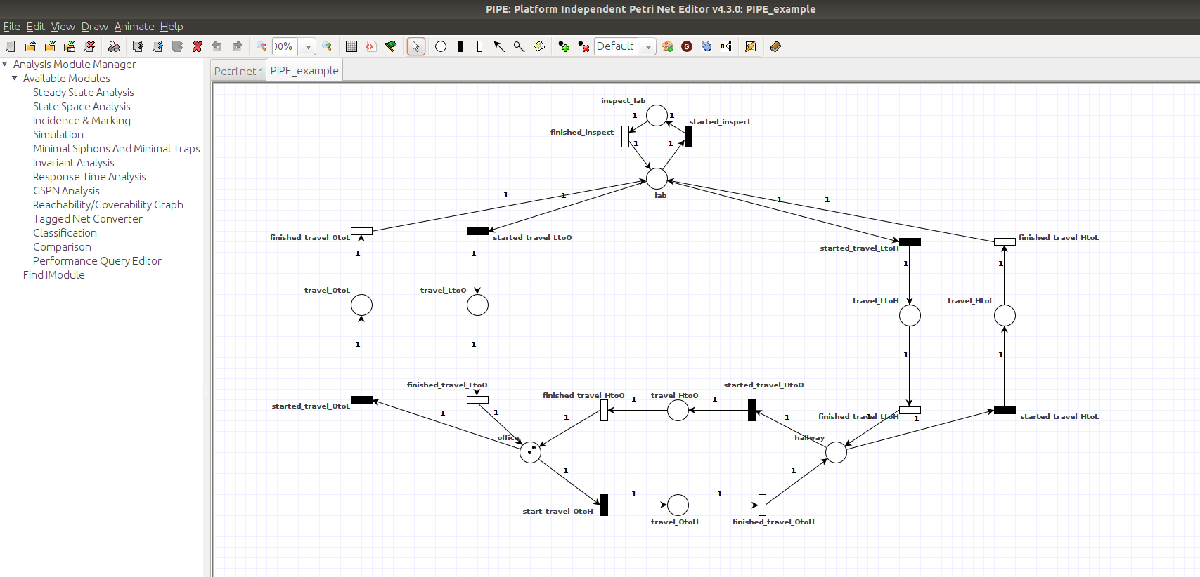

PIPE_path = 'PIPE_example.xml';
gspn = ImportfromPIPE(PIPE_path);

This function imports a single GSPNR from PIPE, using the default save file used (".xml" extension).

## Mixed Approach

When trying to model multi-robot systems using GSPNRs, even small systems are cumbersome to create manually, and it normally involves repeating the same basic structure multiple times to model the same action done in different states or locations.

This toolbox provides an utility function to create GSPNRs in a programatic way, using a topological map where the nodes represent the different locations the robot can be at, and edges represent how these locations are spatially distributed.

The utility function that accomplishes this is GSPNRCreationfromTopMap(). It takes as input:

- **topological_map: **Digraph object - holds the topological map of the multi-robot system.

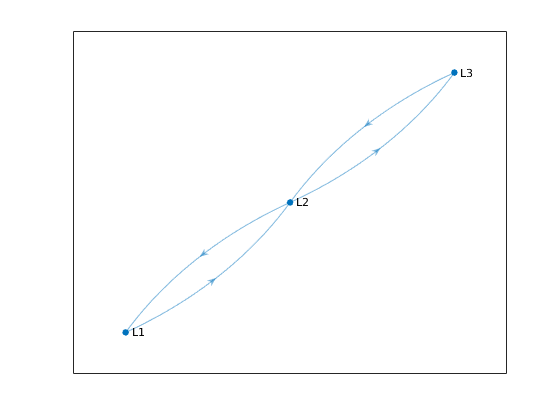

topological_map = digraph(adjacency_matrix, {'L1' 'L2' 'L3'}, 'omitselfloops');
plot(topological_map)

- **actions_available: **Structure (with fields with the same node names found in the **topological_map** input) -  Each field points to a string array with the actions that can be executed in that particular location:

actions_available.L1 = ["mopping", "vacuuming"];
actions_available.L2 = ["mopping", "vacuuming"];
actions_available.L3 = ["mopping", "vacuuming"];

- **robot_marking: **Structure (with fields with the same node names found in the **topological_map** input) - Each field points to an integer representing the number of robots that start out in that particular location:

robot_marking.L1 = 1;
robot_marking.L3 = 1;

- **models: **Structure (with fields with the same names as the ones found in the **actions_available** input) - Each field points to the generic GSPNR modelling the action. These GSPNs have some particularities: they must be created in GreatSPN, and the elements of the GSPNs that change for each location must have a "<1>" tag in their name.

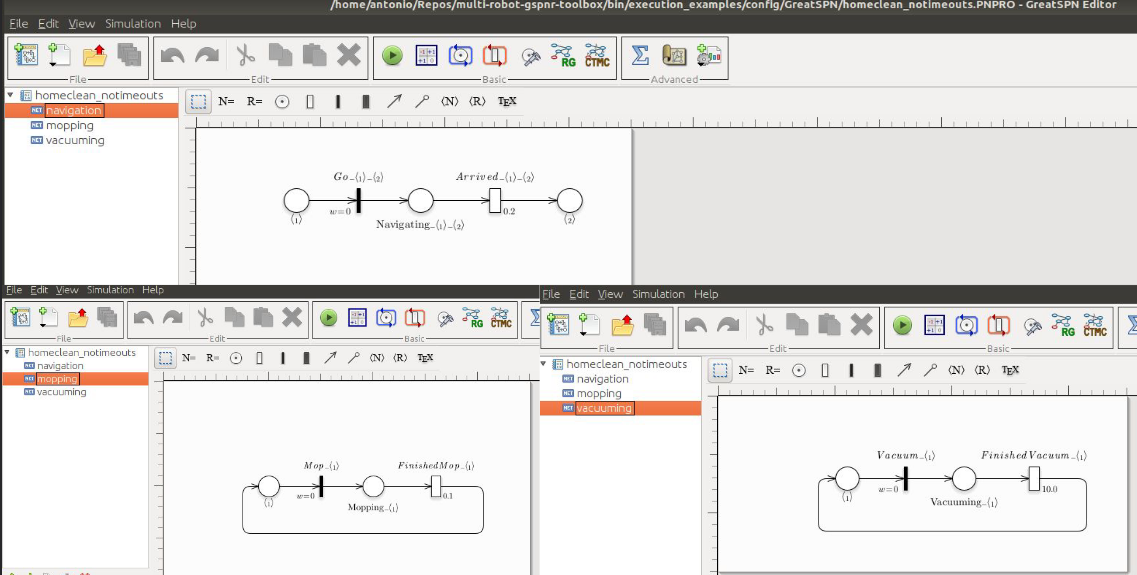

PNPRO_path = "homeclean_with_timeouts.PNPRO";

[nGSPN, models] = ImportfromGreatSPN(PNPRO_path);

Finally, the GSPNR that models the multi-robot system can be created:

home_GSPNR = GSPNRCreationfromTopMap(topological_map, actions_available, models, robot_marking)

home_GSPNR =   GSPNR with properties:

                places: [1×25 string]
           transitions: [1×26 string]
      type_transitions: [1×26 string]
      rate_transitions: [0 0.1000 0.0100 0 0.1000 0.0100 0 0.1000 0.0100 0 0.1000 0.0100 0 0.1000 0.0100 0 0.1000 0.0100 0 1 0 1 0 1 0 1]
            input_arcs: [25×26 double]
           output_arcs: [26×25 double]
                  arcs: [1×1 struct]
       initial_marking: [0 0 1 0 0 1 0 0 1 0 0 1 0 0 1 0 0 1 0 0 1 0 0 0 1]
       current_marking: [0 0 1 0 0 1 0 0 1 0 0 1 0 0 1 0 0 1 0 0 1 0 0 0 1]
         place_rewards: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
    transition_rewards: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]


## Notes:

- After importing from GreatSPN or PIPE, or even using the GSPNRCreationfromTopMap() function, the object is an ordinary GSPNR object, which you can modify using all the available class methods.